### Data Preprocessing

Get ready for the training. The inputs of the proposed models in [2] are the extracted features, which are obtained by the uniform sampling of the raw battery data. Specifically, they configure the input matrix as 30-dimensional vectors by concatenating the V, I, T charging profiles, each with 10 samples. The number of samples is chosen to consider the distinct changes in time and the model complexity. In addition, we average the data over sampling interval to prevent oscillation in short time interval.

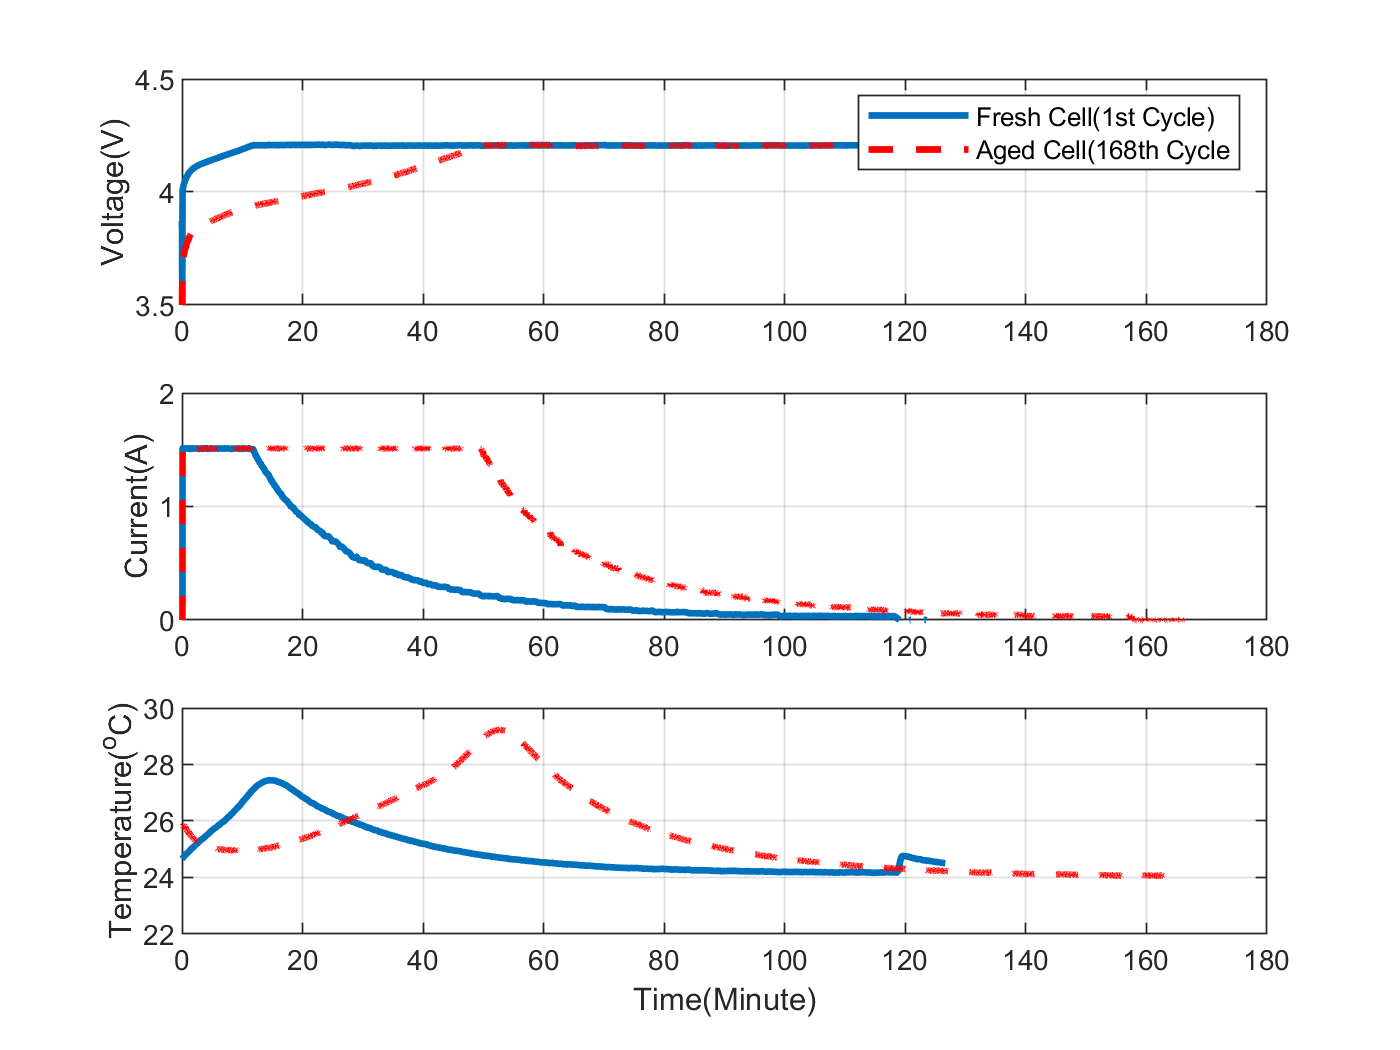

load B0005.mat
load B0006.mat
load B0007.mat

FTime = B0005.cycle(1).data.Time/60;
FreshCell_V = B0005.cycle(1).data.Voltage_measured;
FreshCell_I = B0005.cycle(1).data.Current_measured;
FreshCell_T = B0005.cycle(1).data.Temperature_measured;

ATime = B0005.cycle(168).data.Time/60;
AgedCell_V = B0005.cycle(168).data.Voltage_measured;
AgedCell_I = B0005.cycle(168).data.Current_measured;
AgedCell_T = B0005.cycle(168).data.Temperature_measured;

figure(1)
subplot(311)
plot(FTime, FreshCell_V, 'linewidth', 2), hold on, plot(ATime, AgedCell_V, 'r--','linewidth', 2)
hold off, legend('Fresh Cell(1st Cycle)', 'Aged Cell(168th Cycle'), ylabel('Voltage(V)')
ylim([3.5 4.5]), grid on
subplot(312)
plot(FTime, FreshCell_I, 'linewidth', 2), hold on, plot(ATime, AgedCell_I, 'r--', 'linewidth', 2)
hold off, ylabel('Current(A)'), ylim([0 2]), grid on
subplot(313)
plot(FTime, FreshCell_T, 'linewidth', 2), hold on, plot(ATime, AgedCell_T, 'r--', 'linewidth', 2)
hold off, ylabel('Temperature(^oC)'), ylim([22 30]), grid on, xlabel Time(Minute)




cap5 = extract_discharge(B0005); % 각 방전사이클에서 capacity를 추출한다.

cap6 = extract_discharge(B0006);
cap7 = extract_discharge(B0007);

charInput5 = extract_charge_preprocessing(B0005);% 충전 사이클에서 전압,전류,온도를 읽어온다. %전체 사이클 정보가 들어가 있다.


    


charInput6 = extract_charge_preprocessing(B0006);
charInput7 = extract_charge_preprocessing(B0007);

discharInput5 = extract_discharge_preprocessing(B0005);



Initial capacity for each battery data is provided as belows in the dataset:

InitC5 = 1.86; % capacity of dischage cycle 1
InitC6 = 2.04;
InitC7 = 1.89;

For better training since it retains the original distribution of data except for a scaling factor and transforms all the data into the range of [0,1]:

[xB5, yB5, ym5, yr5] = minmax_norm(charInput5, InitC5, cap5);
[xB6, yB6, ym6, yr6] = minmax_norm(charInput6, InitC6, cap6);
[xB7, yB7, ym7, yr7] = minmax_norm(charInput7, InitC7, cap7);

### Machine Learning models to test

We will experiment 5 machine learning models to compare the prediction result.

Starting with FNN(Feed Forward Neural Network), we will also test CNN(Convolutional Neural Network) and LSTM(Long-Short Term Memory Network) for capacity estimation.

For FNN, we will test both for 10 and 40 hidden neurons, and also for CNN, varying the number of filter of convolution layer.